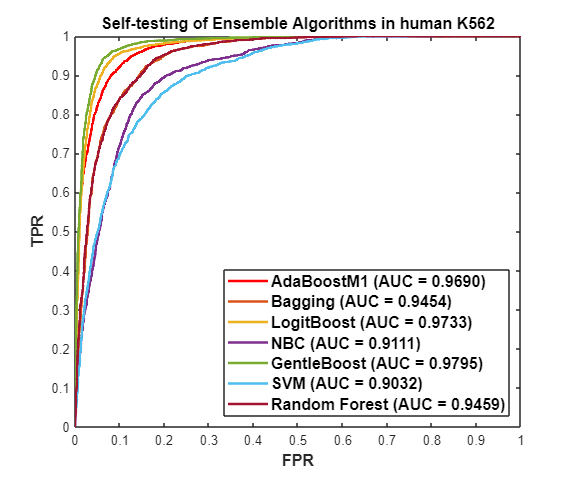

%%



anycell = "K562"; % 只更改细胞名称
openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
fileID = fopen(openfile);
TrainwindowdatadisKc167 = textscan(fileID, '%s %f %f %f %f %f %f %f');
trainingdischiapetKc167 = [TrainwindowdatadisKc167{2:8}];

predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
predictors = inputTable(:, predictorNames);
response = inputTable.column_7;

% 训练 AdaBoostM1 模型
templateAdaBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleAdaBoost = fitcensemble(predictors, response, 'Method', 'AdaBoostM1', 'NumLearningCycles', 30, 'Learners', templateAdaBoost, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
[validationPredictionsAdaBoost, validationScoresAdaBoost] = kfoldPredict(crossval(classificationEnsembleAdaBoost, 'KFold', 10));

% 训练 Bagging 模型
templateBag = templateTree('MaxNumSplits', 30);
classificationEnsembleBag = fitcensemble(predictors, response, 'Method', 'Bag', 'NumLearningCycles', 30, 'Learners', templateBag, 'ClassNames', [1; 2]);
[validationPredictionsBag, validationScoresBag] = kfoldPredict(crossval(classificationEnsembleBag, 'KFold', 10));

% 训练 LogitBoost 模型
templateLogitBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleLogitBoost = fitcensemble(predictors, response, 'Method', 'LogitBoost', 'NumLearningCycles', 30, 'Learners', templateLogitBoost, 'ClassNames', [1; 2]);
[validationPredictionsLogitBoost, validationScoresLogitBoost] = kfoldPredict(crossval(classificationEnsembleLogitBoost, 'KFold', 10));

% 训练 NBC 模型
classificationNBC = fitcnb(predictors, response, 'ClassNames', [1; 2]);
[~, validationScoresNBC] = predict(classificationNBC, predictors);

% 训练 GentleBoost 模型
templateGentleBoost = templateTree('MaxNumSplits', 30);
classificationEnsembleGentleBoost = fitcensemble(predictors, response, 'Method', 'GentleBoost', 'NumLearningCycles', 30, 'Learners', templateGentleBoost, 'LearnRate', 0.8, 'ClassNames', [1; 2]);
[validationPredictionsGentleBoost, validationScoresGentleBoost] = kfoldPredict(crossval(classificationEnsembleGentleBoost, 'KFold', 10));

% 训练 SVM 模型
classificationSVM = fitcsvm(predictors, response);
[~, validationScoresSVM] = predict(classificationSVM, predictors);

% 训练 KNN 模型
%classificationKNN = fitcknn(predictors, response);
%[~, validationScoresKNN] = predict(classificationKNN, predictors);

% 训练随机森林模型
templateRF = templateTree('MaxNumSplits', 30);
classificationEnsembleRF = fitcensemble(predictors, response, 'Method', 'Bag', 'NumLearningCycles', 30, 'Learners', templateRF, 'ClassNames', [1; 2]);
[validationPredictionsRF, validationScoresRF] = kfoldPredict(crossval(classificationEnsembleRF, 'KFold', 10));

% 计算并绘制 ROC 曲线
figure;
hold on;

[XsvmAdaBoost, YsvmAdaBoost, TsvmAdaBoost, AUCsvmAdaBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresAdaBoost(:, 1), 1);
plot(XsvmAdaBoost, YsvmAdaBoost, 'LineWidth', 1.9, 'DisplayName', 'AdaBoostM1','Color', [1, 0, 0]);

[XsvmBag, YsvmBag, TsvmBag, AUCsvmBag] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresBag(:, 1), 1);
plot(XsvmBag, YsvmBag, 'LineWidth', 1.9, 'DisplayName', 'Bagging');

[XsvmLogitBoost, YsvmLogitBoost, TsvmLogitBoost, AUCsvmLogitBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresLogitBoost(:, 1), 1);
plot(XsvmLogitBoost, YsvmLogitBoost, 'LineWidth', 1.9, 'DisplayName', 'LogitBoost');

[XsvmNBC, YsvmNBC, TsvmNBC, AUCsvmNBC] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresNBC(:, 1), 1);
plot(XsvmNBC, YsvmNBC, 'LineWidth', 1.9, 'DisplayName', 'NBC');

[XsvmGentleBoost, YsvmGentleBoost, TsvmGentleBoost, AUCsvmGentleBoost] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresGentleBoost(:, 1), 1);
plot(XsvmGentleBoost, YsvmGentleBoost, 'LineWidth', 1.9, 'DisplayName', 'GentleBoost');

[XsvmSVM, YsvmSVM, TsvmSVM, AUCsvmSVM] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresSVM(:, 1), 1);
plot(XsvmSVM, YsvmSVM, 'LineWidth', 1.9, 'DisplayName', 'SVM');

%[XsvmKNN, YsvmKNN, TsvmKNN, AUCsvmKNN] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresKNN(:, 1), 1);
%plot(XsvmKNN, YsvmKNN, 'LineWidth', 1.9, 'DisplayName', 'KNN');

[XsvmRF, YsvmRF, TsvmRF, AUCsvmRF] = perfcurve(trainingdischiapetKc167(:, 7), validationScoresRF(:, 1), 1);
plot(XsvmRF, YsvmRF, 'LineWidth', 1.9, 'DisplayName', 'Random Forest');

% 计算 AUC 值
AUCsvmAdaBoost = round(AUCsvmAdaBoost, 4);
AUCsvmBag = round(AUCsvmBag, 4);
AUCsvmLogitBoost = round(AUCsvmLogitBoost, 4);
AUCsvmNBC = round(AUCsvmNBC, 4);
AUCsvmGentleBoost = round(AUCsvmGentleBoost, 4);
AUCsvmSVM = round(AUCsvmSVM, 4);
%AUCsvmKNN = round(AUCsvmKNN, 4);
AUCsvmRF = round(AUCsvmRF, 4);

% 创建图例文本
legendText = {
sprintf('AdaBoostM1 (AUC = %.4f)', AUCsvmAdaBoost),
sprintf('Bagging (AUC = %.4f)', AUCsvmBag),
sprintf('LogitBoost (AUC = %.4f)', AUCsvmLogitBoost),
sprintf('NBC (AUC = %.4f)', AUCsvmNBC),
sprintf('GentleBoost (AUC = %.4f)', AUCsvmGentleBoost),
sprintf('SVM (AUC = %.4f)', AUCsvmSVM),
%sprintf('KNN (AUC = %.4f)', AUCsvmKNN),
sprintf('Random Forest (AUC = %.4f)', AUCsvmRF)
};

% 设置图例和标签
xlabel('FPR', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('TPR', 'FontSize', 12, 'FontWeight', 'bold');
title('Self-testing of Ensemble Algorithms in human K562', 'FontSize', 12, 'FontWeight', 'bold');

% 设置图例在右下角
%legend(legendText, 'Location', 'southeast', 'TextColor', 'black', 'FontSize', 12, 'FontWeight', 'bold');
legend(legendText, 'Location', 'southeast', 'TextColor', 'black', 'FontSize', 12,'FontWeight', 'bold');
box on; % 添加边框到整个图形

% 设置坐标轴为正方形
%%%%%%%axis square;
width = 6; % 设置宽度为6英寸
height = width / 1.2; % 计算高度

set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);


hold off;

% 保存图像为 PNG 文件
pngString = sprintf("Comparison_ROC_curve_with_AUChuman.png");
print(gcf, pngString, '-dpng', '-r600'); 